# `Machine Learning Coursework - Naive Bayes Classifier`

#### `Alessandro Alviani `

`City University, December 2021`

train = readtable("train_eng_2.csv");
test = readtable('test_eng_2.csv');

### `Train and test set for crossvalidation`

rng(0)
cvp = cvpartition(train.Stay, "KFold", 5)  % Kfolding on the training set to use for crossvalidation. 

cvp = K-fold cross validation partition
   NumObservations: 409816
       NumTestSets: 5
         TrainSize: 327853  327852  327853  327853  327853
          TestSize: 81963  81964  81963  81963  81963

## `Plotting the ditributions `

`We alrady know this distributions but this is a goodf validation.`

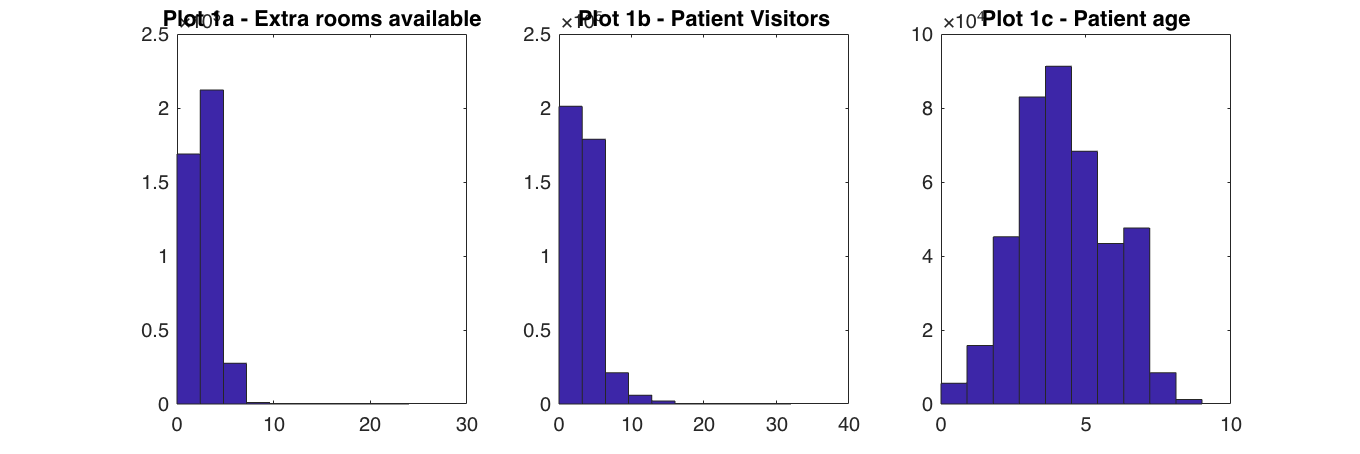

% feature distributions plots
figure()
set(gcf,'position',[10, 10 , 3000 , 1000]) 
subplot(1,3,1);
hist(train.Extra_Rooms)
title('Plot 1a - Extra rooms available')
subplot(1,3,2);
hist(train.Visitors_Patient);
title('Plot 1b - Patient Visitors')
subplot(1,3,3)
hist(train.Age)
title('Plot 1c - Patient age')
hold off

## `Naive Bayes Classifier - untuned`

`The below section wants to be a quick implementation just to see how an untuned tree would behave on our test sets.`

tic
Model = fitcnb(train, 'Stay'); % fit the tree on the training set and sets to tune it on the cross validation partitions. 
% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity, fdr
model_loss = loss(Model, test, 'Stay'); te_f1_score = f1(Model, test); te_balanced_accuracy = balanced_accuracy(Model, test); te_sen = sensitivity(Model,test);
te_false_neg = fnr(Model, test); te_false_pos = fpr(Model, test); te_spe = specificity(Model, test); fd_r = fdr(Model, test);
%display the test performance
disp("UNTUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss)); disp("F1 score = " + string(te_f1_score)); disp("Balanced accuracy = " + string(te_balanced_accuracy)); disp("Sensitivity= " + string(te_sen)); disp("False negative rate = " + string(te_false_neg));  disp("False positives rate = " + string(te_false_pos)); disp("Specificity = " + string(te_spe)); disp("False Discovery Rate = " + string(fd_r))

UNTUNED MODEL PERFORMANCE:
Loss = 0.24023
F1 score = 0.57408
Balanced accuracy = 0.75977
Sensitivity= 0.69799
False negative rate = 0.30201
False positives rate = 0.17846
Specificity = 0.82154
False Discovery Rate = 0.51247


toc

Elapsed time is 0.433048 seconds.


## `Tuning our Naive Bayes classifier`

`Most of the challenges in our dataset were explored and discussed during the training of our Tree model. In fitting the Naive Bayes classifier we won't repeat some of the steps we already made in the previous work.  `

## `Prior Probabilities on Kfold validation`

`Prior probabilities have great effect on a Naive Bayes classifier (Posterior = Prior * Likelihood). `

`By default the classifier counts the number of labels of each class and divide them by the total number of labels to assign them a prior probabilty. This is the most logical way to estimate that probability, without any prior information. `

`In case we had that knowledge, we would modify those priors. Alternatively we could guess them, as we did below:`

## `Prior Probabilities - Train and Test set`

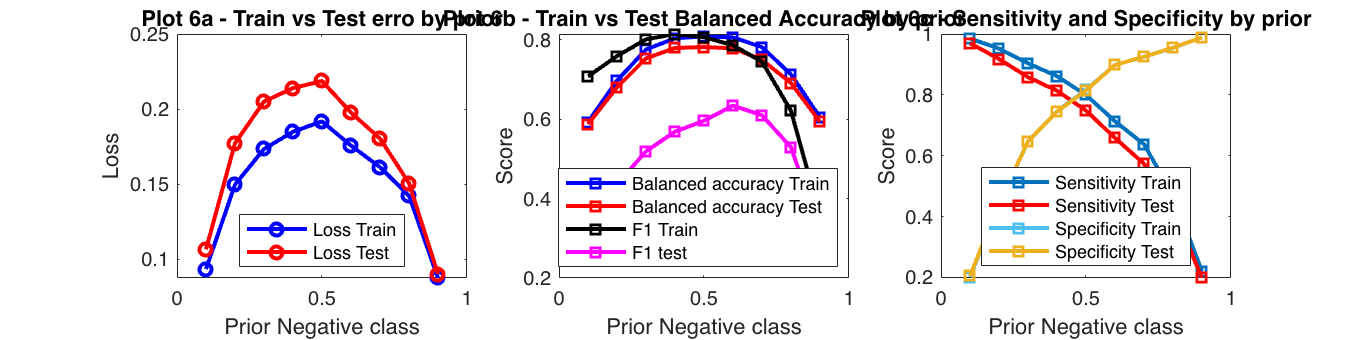

prior_x = [0.9:-0.1:0.1]; % prior probabilty for class 0 (Negative / "Short Stay")
prior_y = [0.1:0.1:0.9]; % prior probabilty for class 1 (Positive/ "Long Stay")
train_loss = zeros(1, numel(prior_x)); % store train here
test_loss = zeros(1, numel(prior_x)); % store test loss
train_ba = zeros(1, numel(prior_x));  % store train balanced accuracy 
test_ba = zeros(1, numel(prior_x));  % store test balanced accuracy 
train_se = zeros(1, numel(prior_x)); % store train sensitivity
test_se = zeros(1, numel(prior_x)); % store test sensitivity
train_sp= zeros(1, numel(prior_x)); % store train specificity
test_sp = zeros(1, numel(prior_x)); % store train specificity
train_f1= zeros(1, numel(prior_x)); % store train f1
test_f1= zeros(1, numel(prior_x)); % store train f1

for i  = 1:length(prior_x)
    prior = [prior_x(i), prior_y(i)];
    Model = fitcnb(train, 'Stay', 'Prior', prior , 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'} );
    train_loss(i) = loss(Model, train, 'Stay'); % train loss
    test_loss(i) = loss(Model, test, 'Stay'); % test loss 
    train_ba(i) = balanced_accuracy(Model, train); % train balanced accuracy
    test_ba(i) = balanced_accuracy(Model, test); % test balanced accuracy
    train_f1(i) = f1(Model, train); % train f1
    test_f1(i) = f1(Model, test); % test f1
    train_se(i) = sensitivity(Model, train); % train sensitivity
    test_se(i) = sensitivity(Model, test); % train specificity
    train_sp(i) = specificity(Model, train); % train specificity
    test_sp(i) = specificity(Model, test); % test specificity

end

figure();
set(gcf,'position',[10, 10 , 3000 , 750]);
% subplot 1 
subplot(1,3,1);
plot(prior_x, train_loss, '-ob', 'LineWidth',2);
hold on;
plot(prior_x, test_loss, '-or', 'LineWidth',2);
title('Plot 6a - Train vs Test erro by prior');
xlabel('Prior Negative class');
ylabel('Loss');
legend('Loss Train','Loss Test', 'Location','south');
% subplot 2 
subplot(1,3,2);
plot(prior_x, train_ba, '-sb', 'LineWidth',2);
hold on;
plot(prior_x, test_ba, '-sr', 'LineWidth',2);
plot(prior_x, train_f1, '-sr', 'LineWidth',2, Color='black');
plot(prior_x, test_f1, '-sr', 'LineWidth',2, Color='magenta');
title('Plot 6b - Train vs Test Balanced Accuracy by prior');
xlabel('Prior Negative class');
ylabel('Score');
legend('Balanced accuracy Train', 'Balanced accuracy Test', 'F1 Train','F1 test', 'Location','south');
% subplot 3
subplot(1,3,3);
plot(prior_x, train_se, '-sb', 'LineWidth',2, Color ='#0072BD');
hold on;
plot(prior_x, test_se, '-sr', 'LineWidth',2);
plot(prior_x, train_sp, '-sr', 'LineWidth',2, Color='#4DBEEE');
plot(prior_x, test_sp, '-sr', 'LineWidth',2, Color='#EDB120');

title('Plot 6c - Sensitivity and Specificity by prior');
xlabel('Prior Negative class');
ylabel('Score');
legend('Sensitivity Train', 'Sensitivity Test','Specificity Train', 'Specificity Test', 'Location','best');

`Above we can see how our loss and score functions respond to the different priors. More on this at the end.`

## `Subset training set`

`The Naive Bayes classifier trained with categorical predictors can be much more computationally expensive than the Decision Tree. `

`To use MatLab in-built hyperparameters optimization we took a random sample of 10000 instances from our training dataset. `

n = randperm(size(train,1));
train_sub = train(n(1:10000),:); % takes a subset of 10000 random rows from our training set. 

rng(0)
sub_cvp = cvpartition(train_sub.Stay, "KFold", 5); % Kfolding on the subset/ 

## `Hyperparameters optimisation`

`Note - this optimization wasn't possible on our full dataset and when we subset it to 50.000 it still took about 7 minutes. `

op = struct('Optimizer','bayesopt','ShowPlots',false,'AcquisitionFunctionName','expected-improvement-plus','verbose',1,'CVPartition', sub_cvp); % optimization settings and crossvalidation
Model = fitcnb(train_sub, 'Stay' ,'Prior', [0.6,0.4],'OptimizeHyperparameters','all', 'CategoricalPredictors', { 'Extra_Rooms','Ward_Type', 'Severity_Illness', 'Visitors_Patient'}, 'HyperparameterOptimizationOptions', op) % optimizying the model on a 60/40 prior. 

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |       Kernel |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |              |
|====================================================================================================================|
|    1 | Best   |     0.17201 |      2.0646 |     0.17201 |     0.17201 |       kernel |       15.576 |     triangle |
|    2 | Accept |      0.1778 |     0.30697 |     0.17201 |     0.17286 |       kernel |       0.3498 | epanechnikov |
|    3 | Accept |     0.17381 |     0.12725 |     0.17201 |     0.17363 |       normal |            - |            - |
|    4 | Accept |     0.17381 |     0.13579 |     0.17201 |     0.17201 |       normal |            - |            - |
|    5 | Accept |     0.17257 |      0.6896 |   

Model =   ClassificationNaiveBayes
                       PredictorNames: {'Extra_Rooms'  'Ward_Type'  'Severity_Illness'  'Visitors_Patient'  'Age'}
                         ResponseName: 'Stay'
                CategoricalPredictors: [1 2 3 4]
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 10000
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                    DistributionNames: {'mvmn'  'mvmn'  'mvmn'  'mvmn'  'kernel'}
               DistributionParameters: {2×5 cell}
                    CategoricalLevels: {[11×1 double]  [5×1 double]  [3×1 double]  [24×1 double]  []}
                               Kernel: {[]  []  []  []  'normal'}
                              Support: {[]  []  []  []  'unbounded'}
                                Width: [2×5 double]


  Properties

### Performance and speed 

tic
% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity
model_loss = loss(Model, test, 'Stay'); te_f1_score = f1(Model, test); te_balanced_accuracy = balanced_accuracy(Model, test); te_sen = sensitivity(Model,test);
te_false_neg = fnr(Model, test); te_false_pos = fpr(Model, test); te_spe = specificity(Model, test);
%display the test performance
disp("TUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss)); disp("F1 score = " + string(te_f1_score)); disp("Balanced accuracy = " + string(te_balanced_accuracy)); disp("Sensitivity= " + string(te_sen)); disp("False negative rate = " + string(te_false_neg));  disp("False positives rate = " + string(te_false_pos)); disp("Specificity = " + string(te_spe))

TUNED MODEL PERFORMANCE:
Loss = 0.19418
F1 score = 0.63922
Balanced accuracy = 0.78325
Sensitivity= 0.67039
False negative rate = 0.32961
False positives rate = 0.10389
Specificity = 0.89611


toc

Elapsed time is 90.411273 seconds.


`The above optimization assigns the numerical variable to a kernel distribution and that makes the model several times slower than before. `

### `Difference in accuracy and speed (Normal vs Kernel)`

`Below we can see how the model has a minor loss in performance when we assign the "age" variable to a normal distribution instead of kernel, but also the huge improvement in terms of speed. `

tic
% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity
Model = fitcnb(train, 'Stay', 'Prior', [0.5, 0.5], 'DistributionNames', {'mvmn', 'mvmn', 'mvmn', 'mvmn', 'normal'}, 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'});
model_loss = loss(Model, test, 'Stay'); te_f1_score = f1(Model, test); te_balanced_accuracy = balanced_accuracy(Model, test); te_sen = sensitivity(Model,test);
te_false_neg = fnr(Model, test); te_false_pos = fpr(Model, test); te_spe = specificity(Model, test);
%display the test performance
disp("TUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss)); disp("F1 score = " + string(te_f1_score)); disp("Balanced accuracy = " + string(te_balanced_accuracy)); disp("Sensitivity= " + string(te_sen)); disp("False negative rate = " + string(te_false_neg));  disp("False positives rate = " + string(te_false_pos)); disp("Specificity = " + string(te_spe))

TUNED MODEL PERFORMANCE:
Loss = 0.21873
F1 score = 0.59583
Balanced accuracy = 0.78127
Sensitivity= 0.74815
False negative rate = 0.25185
False positives rate = 0.18562
Specificity = 0.81438


toc

Elapsed time is 0.547744 seconds.


## Effects of different priors on the confusion matrix

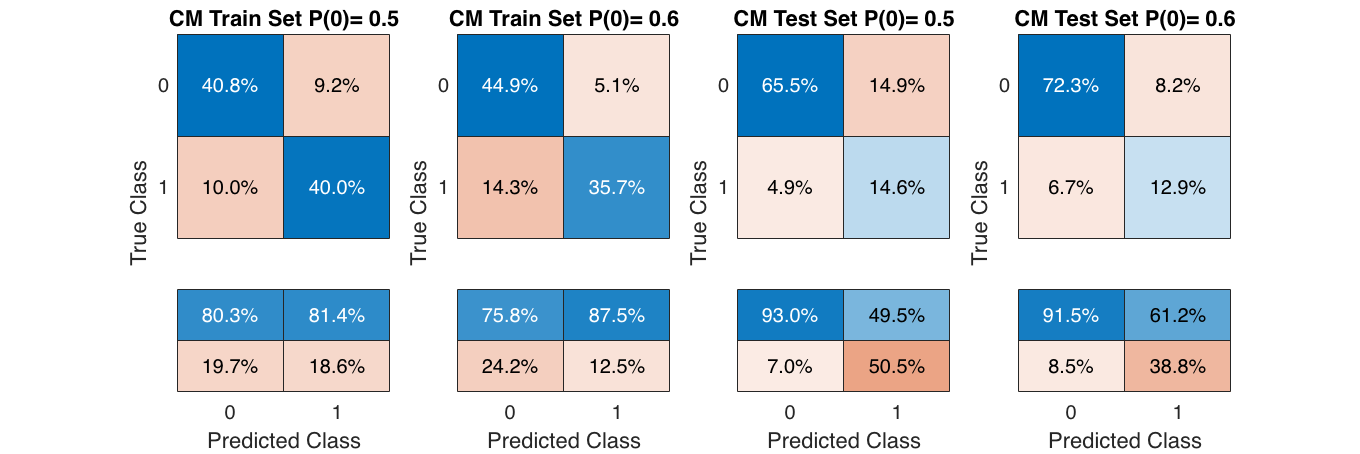

mdl = fitcnb(train, 'Stay', 'Prior', [0.5, 0.5] , 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'} ); % train first model with 50/50 priors
mdl_2 = fitcnb(train, 'Stay', 'Prior', [0.6, 0.4] , 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'} ); % train first model with 70/30 priors
labels_1 = predict(mdl, train);
labels_2 = predict(mdl_2, train);
labels_1t = predict(mdl, test); % predicted labels 
labels_2t = predict(mdl_2, test); % predicted labels 
figure()
set(gcf,'position',[10, 10 , 3000 , 1000])
subplot(1,4,1)
conf_chart_1 = confusionchart(train.Stay, labels_1, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_1.Title = "CM Train Set P(0)= 0.5";
subplot(1,4,2)
conf_chart_2 = confusionchart(train.Stay, labels_2, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_2.Title = "CM Train Set P(0)= 0.6";
subplot(1,4,3)
conf_chart_2 = confusionchart(test.Stay, labels_1t, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_2.Title = "CM Test Set P(0)= 0.5";
subplot(1,4,4)
conf_chart_2 = confusionchart(test.Stay, labels_2t, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_2.Title = "CM Test Set P(0)= 0.6";

`Above we see the effects of changing the priors. Studying the confusion matrixes in pairs (Train pair on the left | Test pair on the right) we notice how changing priors influences False Positives and False negatives.  `

## `Kernels `

`Testing different types of kernel on our single kernel predictor`

kernels = ["epanechnikov", "normal", "triangle"];
for i = 1:length(kernels)
    Model = fitcnb(train_sub, 'Stay', 'Prior',  [0.6,0.4], 'DistributionNames', {'mvmn', 'mvmn', 'mvmn', 'mvmn', 'kernel'}, 'CategoricalPredictors', { 'Extra_Rooms','Ward_Type', 'Severity_Illness', 'Visitors_Patient'}, "Kernel", kernels(i));
    disp("Loss with " + string(kernels(i)) + " = " + string(resubLoss(Model)));
end 

Loss with epanechnikov = 0.17377
Loss with normal = 0.17345
Loss with triangle = 0.17377


## `Changing categorical variables to kernel `

kernels = ["epanechnikov", "normal", "triangle"];
for i = 1:length(kernels)
    Model = fitcnb(train_sub, 'Stay', 'Prior',  [0.6,0.4], 'DistributionNames', {'mvmn', 'mvmn', 'mvmn', 'kernel', 'kernel'}, 'CategoricalPredictors', { 'Extra_Rooms', 'Ward_Type', 'Severity_Illness'}, "Kernel", kernels(i));
    disp("Loss with " + string(kernels(i)) + " = " + string(resubLoss(Model)));
end 

Loss with epanechnikov = 0.29378
Loss with normal = 0.28612
Loss with triangle = 0.28791


`Above what happens if we change the variable 'Visitors with Patient" from categorical to 'kernel'. `

## `Changing categorical variables to normal `

kernels = ["epanechnikov", "normal", "triangle"];
for i = 1:length(kernels)
    Model = fitcnb(train_sub, 'Stay', 'Prior',  [0.6,0.4], 'DistributionNames', {'mvmn', 'mvmn', 'mvmn', 'kernel', 'normal'}, 'CategoricalPredictors', { 'Extra_Rooms', 'Ward_Type', 'Severity_Illness'}, "Kernel", kernels(i));
    disp("Loss with " + string(kernels(i)) + " = " + string(resubLoss(Model)));
end 

Loss with epanechnikov = 0.29514
Loss with normal = 0.28847
Loss with triangle = 0.29135


`Above what happens if we change the variable 'Visitors with Patient" from categorical to 'normal'. `

## `Missclassification cost `

`Below we look at how a different misslcassifiction cost would impact the model.  `

`If we set a custom cost that "penalises" the class we want to improve (minority, class 1), we may be able to balance our accuracy. `

`Note - This may not be needed if we had the same interest in both classes.   `

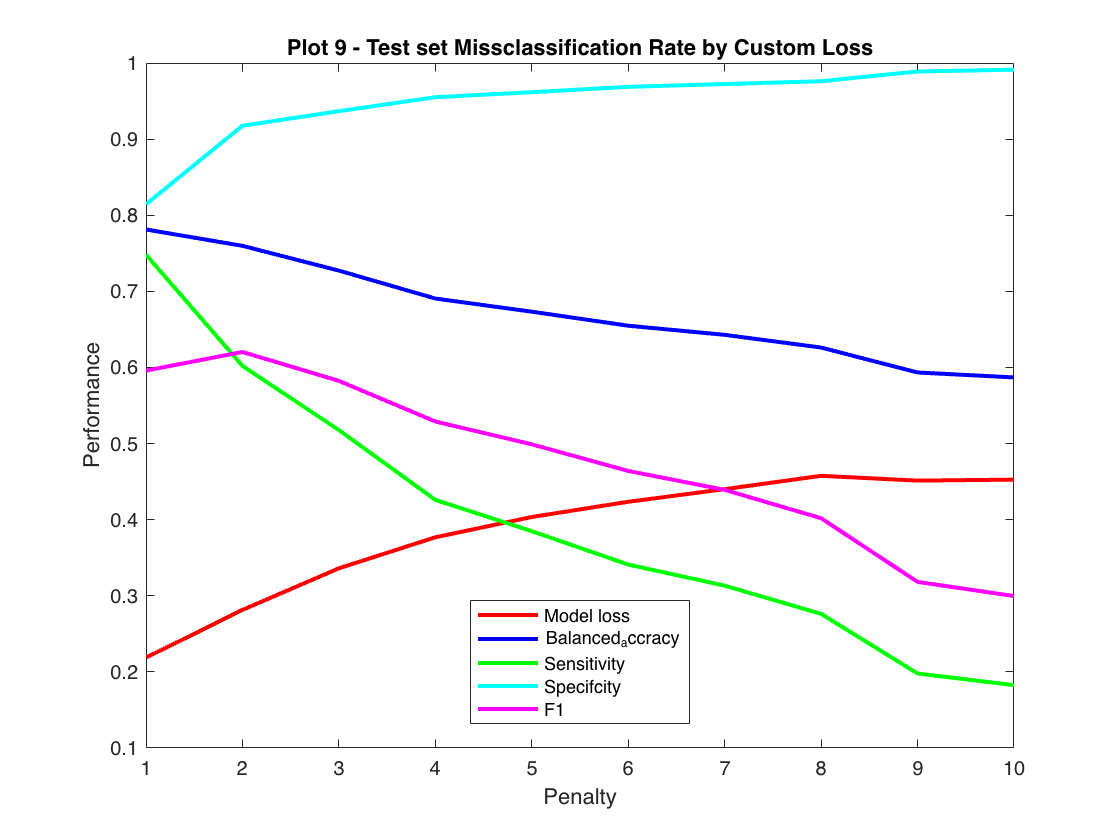

splits = [1:1:10]; % custom loss 
mloss = zeros(1, numel(splits)); % model loss 
b_a_training = zeros(1, numel(splits)); % balanced accuracy
sen = zeros(1, numel(splits)); % false negative rate 
spe = zeros(1, numel(splits)); % false postives rate
f_1 = zeros(1, numel(splits)); % false postives rate

figure;
for split = 1:length(splits)
    mdl = fitcnb(train, 'Stay', 'Prior', [0.5, 0.5] , 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'} , 'Cost', [0, splits(split); 1, 0]); % model trained on different custom losses 
    mloss(split) = loss(mdl, test, 'Stay');
    b_a_trainig(split) = balanced_accuracy(mdl, test);
    sen(split) = sensitivity(mdl, test);
    spe(split) = specificity(mdl, test);
    f_1(split) = f1(mdl, test);

end
% plots below 
figure;
plot(splits, mloss, '-r', 'LineWidth',2);
hold on;
plot(splits, b_a_trainig, '-b', 'LineWidth',2);
plot(splits, sen, '-g', 'LineWidth',2);
plot(splits, spe, '-c', 'LineWidth',2);
plot(splits, f_1, '-', 'LineWidth',2, 'Color', 'magenta');
title('Plot 9 - Test set Missclassification Rate by Custom Loss');
xlabel('Penalty');
ylabel('Performance');
legend('Model loss', 'Balanced_accracy', "Sensitivity", 'Specifcity', "F1", 'Location', 'best')
hold off;

## `Final model `

tic
Model_N = fitcnb(train, 'Stay', 'Prior', [0.60, 0.40], 'DistributionNames', {'mvmn', 'mvmn', 'mvmn', 'mvmn', 'normal'}, 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'});
% first line: model loss (1 - Accuracy), F1, Balanced Accuracy, Sensitivity
% second line: false negative rate, false positive rate, specificity, fdr
model_loss_N = loss(Model_N, test, 'Stay'); te_f1_score_N = f1(Model_N, test); te_balanced_accuracy_N = balanced_accuracy(Model_N, test); te_sen_N = sensitivity(Model_N,test);
te_false_neg_N = fnr(Model_N, test); te_false_pos_N = fpr(Model_N, test); te_spe_N = specificity(Model_N, test); fd_r_N = fdr(Model_N, test);
%display the test performance
disp("TUNED MODEL PERFORMANCE:"); disp("Loss = " + string(model_loss_N)); disp("F1 score = " + string(te_f1_score_N)); disp("Balanced accuracy = " + string(te_balanced_accuracy_N)); disp("Sensitivity= " + string(te_sen_N)); disp("False negative rate = " + string(te_false_neg_N));  disp("False positives rate = " + string(te_false_pos_N)); disp("Specificity = " + string(te_spe_N)); disp("False Discovery Rate = " + string(fd_r_N));

TUNED MODEL PERFORMANCE:
Loss = 0.19769
F1 score = 0.63407
Balanced accuracy = 0.77831
Sensitivity= 0.65835
False negative rate = 0.34165
False positives rate = 0.10172
Specificity = 0.89828
False Discovery Rate = 0.38847


toc

Elapsed time is 0.484299 seconds.


## `Confusion Matrix final model `

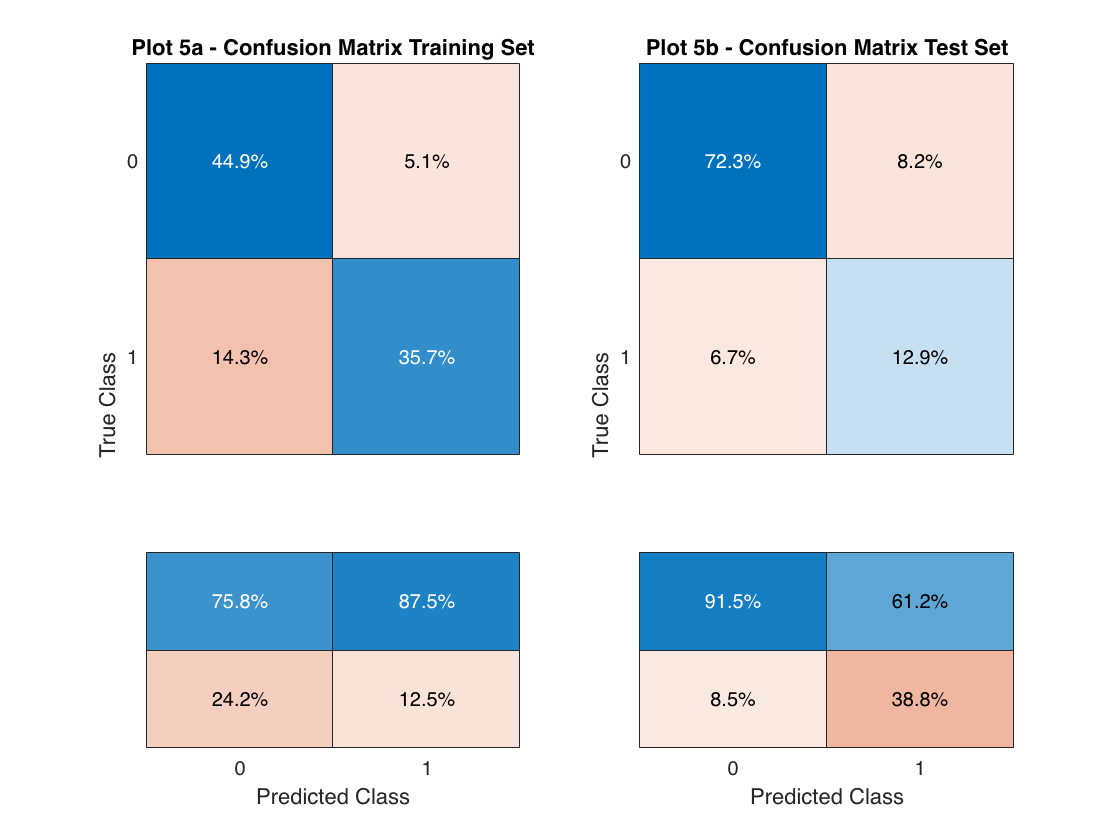

labels_tr = predict(Model_N, train); % predicted labels 
figure();
subplot(1,2,1)
conf_chart_2 = confusionchart(train.Stay, labels_tr, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_2.Title = "Plot 5a - Confusion Matrix Training Set";
labels_te = predict(Model_N, test); % predicted labels 
subplot(1,2,2)
conf_chart_3 = confusionchart(test.Stay, labels_te, 'Normalization','total-normalized', 'ColumnSummary','column-normalized'); % confusion chart
conf_chart_3.Title = "Plot 5b - Confusion Matrix Test Set"; 

## ROC Train vs Test sets

`The receiver operator curve is another way to visualise true positives, false positives and total accuracy.`

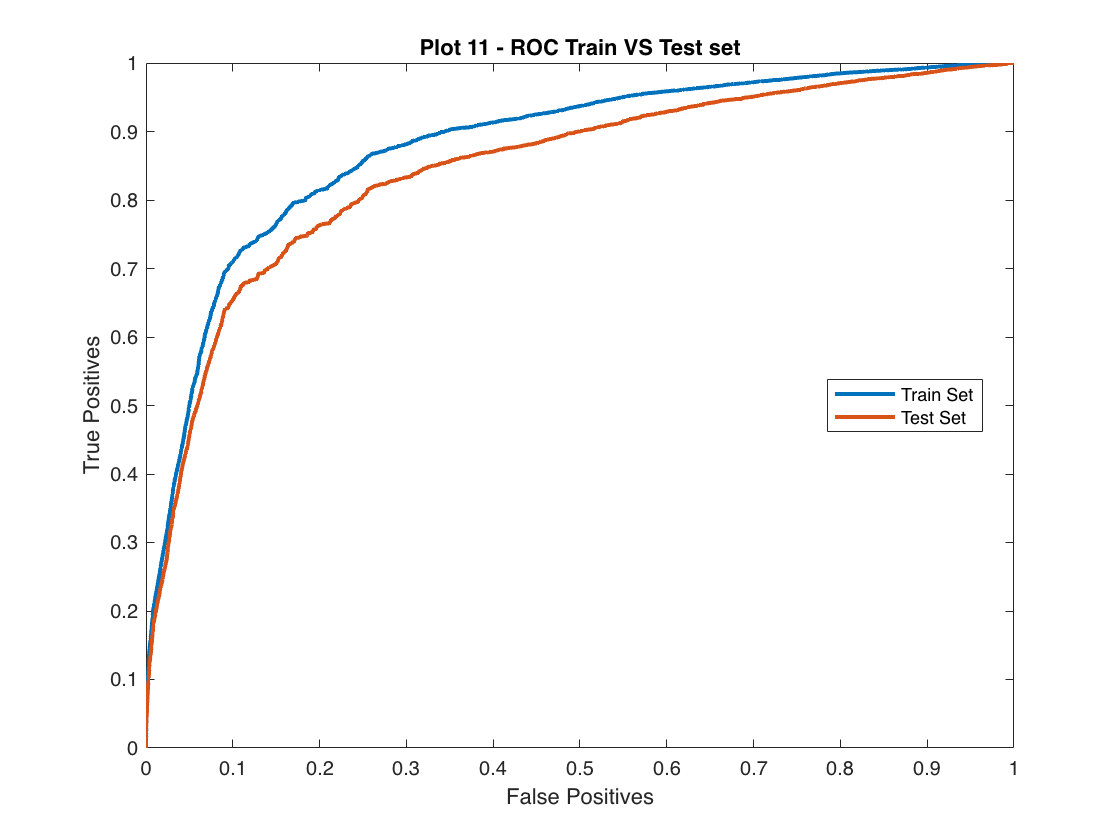

[~,score_train] = resubPredict(Model_N); % returns the scores (probabilities) of each class in the training set 
[label,score_test,cnum] = predict(Model_N, test); % returns the scores (probabilities) of each class in the test set 

[X, y, t, AUC] = perfcurve(train.Stay, score_train(:,2), 1); % ROC train set
[X_t, y_t, t_t, AUC_t] = perfcurve(test.Stay, score_test(:,2), 1); % ROC test set

% plots
figure();
plot(X, y, '-', 'LineWidth', 2)
hold on;
plot(X_t, y_t, '-', 'LineWidth', 2)
xlabel('False Positives');
ylabel('True Positives');
title('Plot 11 - ROC Train VS Test set')
legend('Train Set', 'Test Set', 'Location', 'best')

## `Plots for Poster  `

## `Prior Probabilities - Test set`

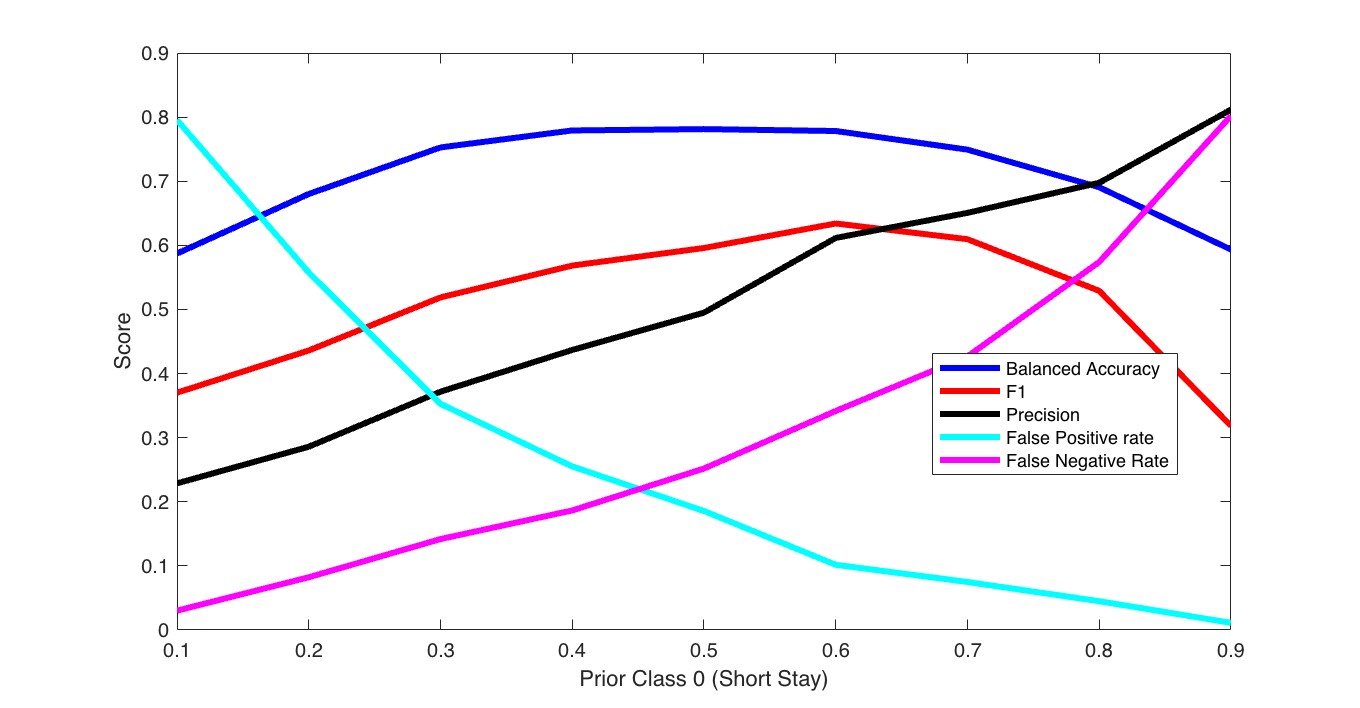

prior_x = [0.9:-0.1:0.1]; % prior probabilty for class 0 (Negative / "Short Stay")
prior_y = [0.1:0.1:0.9]; % prior probabilty for class 1 (Positive/ "Long Stay")
train_loss = zeros(1, numel(prior_x)); % store train here
test_loss = zeros(1, numel(prior_x)); % store test loss
train_ba = zeros(1, numel(prior_x));  % store train balanced accuracy 
test_ba = zeros(1, numel(prior_x));  % store test balanced accuracy 
train_pr = zeros(1, numel(prior_x)); % store train precision
test_pr = zeros(1, numel(prior_x)); % store test precision
train_f1= zeros(1, numel(prior_x)); % store train f1
test_f1= zeros(1, numel(prior_x)); % store train f1
train_fpr= zeros(1, numel(prior_x)); % store train f1
train_fnr= zeros(1, numel(prior_x)); % store train f1
train_fdr= zeros(1, numel(prior_x)); % store train f1

for i  = 1:length(prior_x)
    prior = [prior_x(i), prior_y(i)];
    Model = fitcnb(train, 'Stay', 'Prior', prior , 'CategoricalPredictors', {'Extra_Rooms', 'Ward_Type', 'Severity_Illness', 'Visitors_Patient'} );
    train_loss(i) = loss(Model, train, 'Stay'); % train loss
    test_loss(i) = loss(Model, test, 'Stay'); % test loss 
    train_ba(i) = balanced_accuracy(Model, test); % train balanced accuracy
    test_ba(i) = balanced_accuracy(Model, test); % test balanced accuracy
    train_f1(i) = f1(Model, test); % train f1
    test_f1(i) = f1(Model, test); % test f1
    train_pr(i) = precision(Model, test); % train sensitivity
    test_pr(i) = precision(Model, test); % train specificity
    train_fpr(i) = fpr(Model, test);
    train_fnr(i) = fnr(Model, test);
    train_fdr(i) = fdr(Model, test);
end

figure();
set(gcf,'position',[10, 10 , 2500 , 1300]);
% subplot 1 
plot(prior_x, train_ba, '-b', 'LineWidth',3);
hold on;
plot(prior_x, train_f1, '-r', 'LineWidth',3);
plot(prior_x, train_pr, '-', 'LineWidth',3, 'Color', 'black');
plot(prior_x, train_fpr, '-c', 'LineWidth',3);
plot(prior_x, train_fnr, '-m', 'LineWidth',3);
xlabel('Prior Class 0 (Short Stay)');
ylabel('Score');
legend('Balanced Accuracy', 'F1', 'Precision','False Positive rate', 'False Negative Rate', 'Location', 'best');

## ROC

`The receiver operator curve is another way to visualise true positives, false positives and total accuracy.`

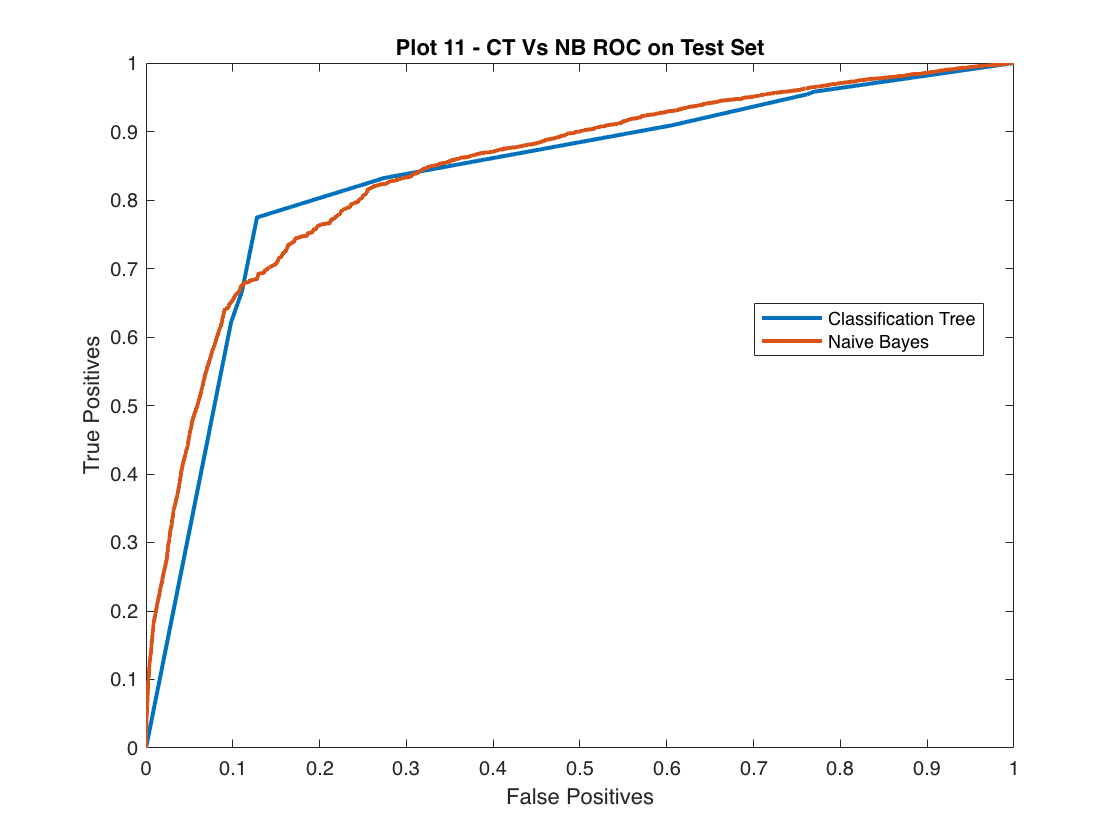

[~,score_test_T] = predict(Model_T, test); % returns the scores (probabilities) of each class on the test set - CT
[~,score_test_N] = predict(Model_N, test); % returns the scores (probabilities) of each class on the test set - NB

[X, y, t, AUC] = perfcurve(test.Stay, score_test_T(:,2), 1); % ROC test set - CT
[X_t, y_t, t_t, AUC_t] = perfcurve(test.Stay, score_test_N(:,2), 1); % ROC test set - NB

%plots
figure();
plot(X, y, '-', 'LineWidth', 2)
hold on;
plot(X_t, y_t, '-', 'LineWidth', 2)
xlabel('False Positives');
ylabel('True Positives');
title('Plot 11 - CT Vs NB ROC on Test Set')
legend('Classification Tree', 'Naive Bayes', 'Location', 'best')

## `Comparison Metrics`

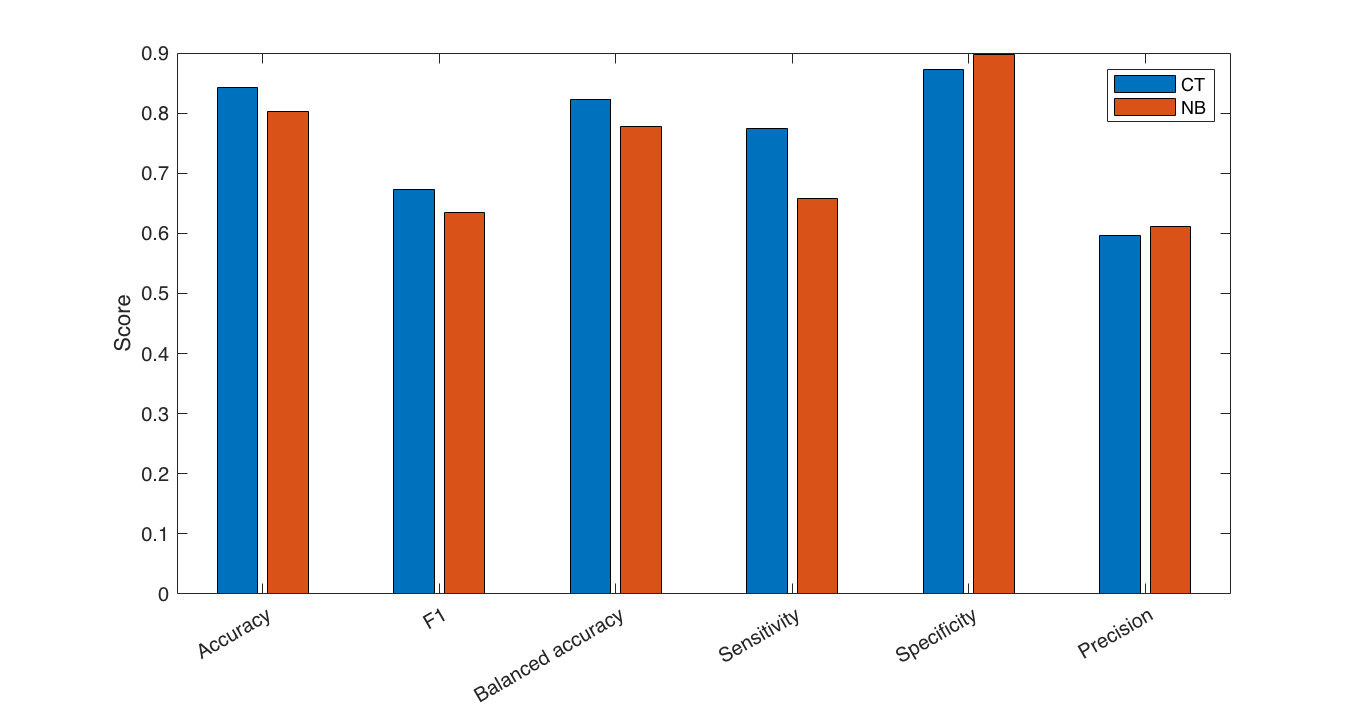

Tree_err = [1 - model_loss_T, te_f1_score_T, te_balanced_accuracy_T,  te_sen_T, te_spe_T,  1 - fd_r_T];
NB_err = [1 - model_loss_N, te_f1_score_N, te_balanced_accuracy_N,  te_sen_N, te_spe_N, 1 - fd_r_N];
errors = [Tree_err; NB_err]';
figure();
set(gcf,'position',[10, 10 , 2500 , 1300]);
plot_err = bar(errors);
legend("CT", "NB", 'Location', 'Northeast')
xticks(1:1:8)
xticklabels({'Accuracy', 'F1', 'Balanced accuracy', 'Sensitivity', 'Specificity', 'Precision'});
ylabel('Score');

%save("final_models", "Model_N", "Model_T", "test"); -- commented out to avoid repeated savings 

load("final_models.mat")

## `Conclusions `

`Given the dataset 4 out of 5 features work better when assigned to a categorical type.`

`The 5th feature ("Age") works better as numerical with a Gaussian distribution. `

`Tuning the priors changes the model's behaviour and could be used to respond to one's beliefs or needs. `

`Tuning the missclassification cost changes the model's behaviour and could be used to one's needs. `